## Shipping Example

% parameters and I.C.
m = 3.600;     % kg
k = 400;    % N/m
b = 20;      % Ns/m
x0=1; % m
open_system("ssc_mass_spring_damper_v1")

% simulate system
sim("ssc_mass_spring_damper_v1")

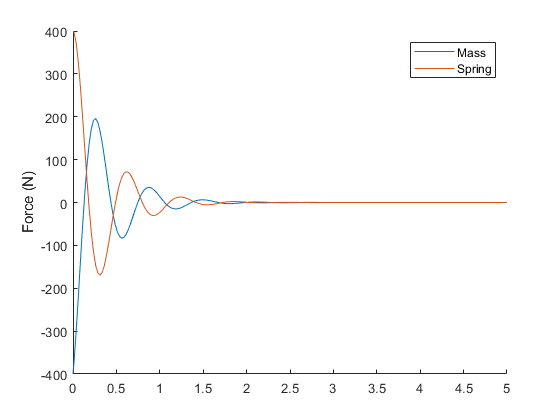

% examine results
time = simlog.Mass.f.series.time;
F_mass = simlog.Mass.f.series.values('N');
F_sprg = simlog.Spring.f.series.values('N');

figure(101); clf;
hold on
plot(time,F_mass)
plot(time,F_sprg)
ylabel('Force (N)')
legend("Mass","Spring")

*Copyright 2021 The MathWorks, Inc.*